## Data Loading

%cd('/Users/ermarinellone/Library/Mobile Documents/com~apple~CloudDocs/AMC/Tutoring activities - Quadruple Tank/Group Work/');
addpath utils;
load('./Data/pump_params.mat');
load('./Data/valve_opening.mat');

## Linearization

S = (4.44 / 2)^2 * pi;
y_target = [10; 10];

sys = struct('A', AA, 'S', S, 'g', 981, 'k1_fcn', k1_fcn, 'k2_fcn', k2_fcn, ...
                'gamma1_fcn', gamma1_fcn, 'gamma2_fcn', gamma2_fcn, ...
                'u_min', 4, 'u_max', 12, 'x_min', 0.1, 'x_max', 30);

[ linsys, x_bar, u_bar ] = linearize_4tanks(sys, y_target);


Local minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>


% Initial state (for simulation)

h0 = [ 2, 2, 2, 2 ].';

Gs = tf(linsys);
A = linsys.A;
B = linsys.B;
C = linsys.C;
D = linsys.D;


% Approximate the maps -> They are implemented via Lookup tables
xv = 0:0.05:18;
yk1 = k1_fcn(xv);
yk2 = k2_fcn(xv);
ygamma1 = gamma1_fcn(xv);
ygamma2 = gamma2_fcn(xv);

## LQR with enlarged system

1) the pair $(A,B)
$ need to be reachable

n = size(A,1);
m = size(B, 2);
p = size(C, 1);

alpha = 0; % performance parameter


tzero(ss(A,B,C,D))

ans =    -0.0654
   -0.0041


No invariant zeros in the origin (but very close to it) $\Rightarrow
$ No derivative action.

System may be enlarged with integrators to reduce the reference-output error.

A_en = [A zeros(n,p); -C zeros(p,p)];
B_en = [B; zeros(p,p)];
C_en = [C zeros(p,p)];
D_en = zeros(p,p);
A_perf = A_en + alpha*eye(n+p);
rank(ctrb(A_perf,B_en))==n+p

ans = logical
   1


2) the pair $(A,C_q)

$ need to be observable

% chosen parameters matrix in order to not exceed with control action
Q = eye(n+p)*0.1;
R = eye(m)*10;


rank(obsv(A_perf,sqrt(Q))) == n+p

ans = logical
   1


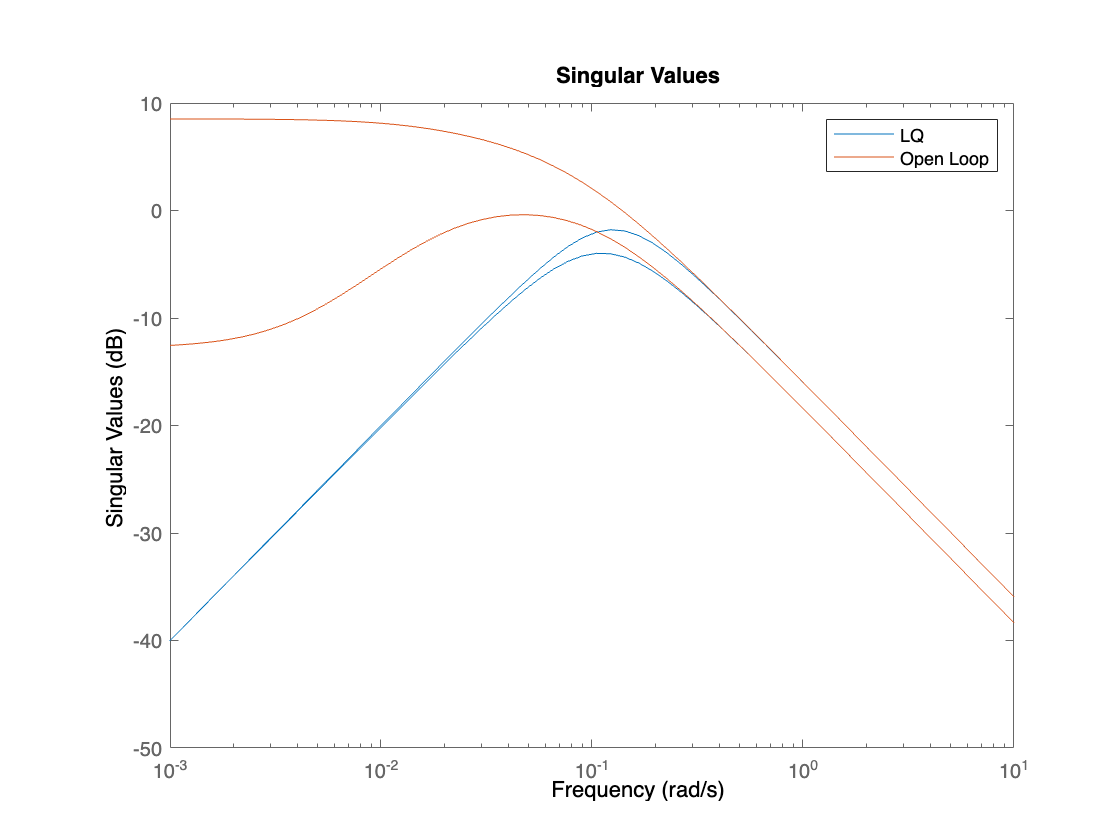

K_lq = lqr(A_perf,B_en,Q,R); 

K_state = K_lq(:,1:n);
K_integrators = K_lq(:,n+1:end);
% eig(A_perf-B_en*K_lq) % check on the poles of the system
L_lqr = tf(ss(A_perf-B_en*K_lq,B_en,C_en,D_en));
sigmaplot(L_lqr, Gs);
legend('LQ', 'Open Loop');

Excellent performances at low freq.

Similar to the open-loop performances at high frequencies.

## Kalman Filtering step

Since the state is not fully observable it is convenient to design a state observer.

   1. $\left(A,C\right)$ is observable

rank(obsv(A,C))==n

ans = logical
   1


Q_tilde = diag([1,0.1,1,0.1]); % trust the states related to measurements
R_tilde = 0.1;                 % trust the measurements

    2. $\left(A,{\tilde{B} }_q \right)$ is reachable

rank(ctrb(A,sqrt(Q_tilde)))==n

ans = logical
   1


L_kf = lqr(A',C',Q_tilde,R_tilde)';


A_kf = A - L_kf*C;
B_kf = [ B - L_kf*D, L_kf]; % B-L_kf because of the input u
C_kf = eye(n);
D_kf = zeros(n,m+p);

open("Control Simulink/CL_LQG.slx")

% after running Simulink model
LQG_data = [out.data4valid.Data(:,:)].';
save("Data/LQ_data.mat","LQG_data")

### PI Decoupled Control with Anti-Windup


R1 = pidtune(Gs(1, 1), 'PI', 0.05);
R2 = pidtune(Gs(2, 2), 'PI', 0.05);

% Backwards-decoupler
T12 = minreal(- Gs(1, 2) / Gs(1, 1));
T21 = minreal(- Gs(2, 1) / Gs(2, 2));
TT = [  0,  T12;
        T21, 0 ];
Delta = inv((eye(2) - TT));

L_decentralized = Gs * blkdiag(R1, R2);
L_decoupled = Gs * Delta * blkdiag(R1, R2);

sigmaplot(L_decentralized, L_decoupled, Gs);
legend('Decentralized', 'Decoupled', 'Open Loop');

### PI Discretization

R1d = c2d(R1, 0.01, 'tustin');
R2d = c2d(R2, 0.01, 'tustin');
T12d = c2d(T12, 0.01, 'tustin');
T21d = c2d(T21, 0.01, 'tustin');
save('Data/DiscretizedController', 'R1d', 'R2d', 'T12d', 'T21d');